clc
clear all

## Import Trained Model

net = importKerasNetwork("my_model.h5",...
    OutputLayerType="classification");
Classes = net.Layers(end).Classes;
% Classes(14) = 'STOP';

## Change Dir

% cd drive-download-20220420T182727Z-001/
imagefiles = dir('*.jpg');
nfiles = length(imagefiles);

## Pre Process

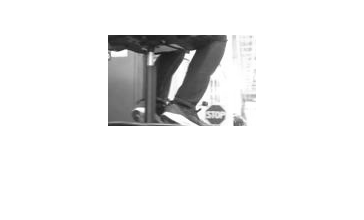

label = categorical
     40 



for i = 1:length(nfiles)
    currentfilename = imagefiles(i).name;
    pic = imread(currentfilename);
    shape = size(pic);
    pic = rgb2gray(pic);
    pic = imcrop(pic,[152.5100   66.5100  147.9800   90.9800]);
    figure(i)
    imshow(pic)

    % Resize the image to the input size of the network.
    InputSize = net.Layers(1).InputSize;
    pic = imresize(pic,InputSize(1:2));

    % Classify the image using the imported network. Show the image with the classification label.
    label(i) = classify(net,pic)
   
    %     imshow(pic)
    %     title(strcat("Predicted label: ",string(label)))
end